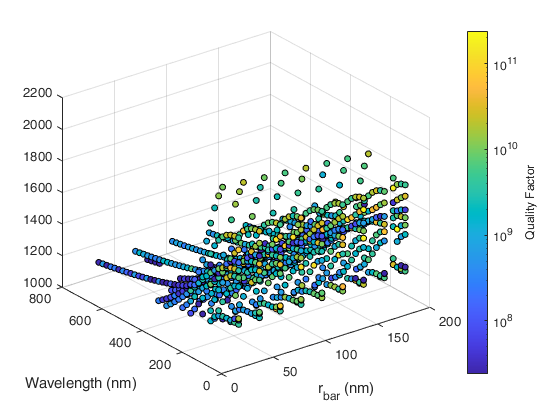

cylinder_dimer_no_substrate_111_0_2


clear;
addpath('C:\Users\Matthew\Documents\MATLAB\COMSOL');
addpath(genpath('C:\Users\Matthew\Documents\MATLAB\COMSOL\analysis'));
addpath('C:\Users\Matthew\Documents\MATLAB\COMSOL\config');
addpath(genpath('C:\Users\Matthew\Documents\MATLAB\COMSOL\jobs\completed'));

fig = figure;

for job = "cylinder_dimer_no_substrate_111_0_2"
    eval(job);
    load([options.output_dir_final 'sweep_data.mat']);
    extra_options = matthew_extra_options(options);
    disp(job);
    
    for study_num = 1:height(sweep_data)
        derived_values = sweep_data(study_num,:).DerivedValues{1};
        high_Q = abs(derived_values.eig.Q)>1e5;
        gap = str2num(erase(sweep_data.gap(study_num), "[nm]"));
        r_bar = str2num(erase(sweep_data.r_bar(study_num), "[nm]"));
    
        scatter3(gap*ones(size(derived_values.eig.Q(high_Q))),...
            r_bar*ones(size(derived_values.eig.Q(high_Q))), derived_values.eig.wavelength(high_Q)*1e9,...
            20,...
            (abs(derived_values.eig.Q(high_Q))),'filled','MarkerEdgeColor','k');
    
        %xlabel('gap (nm)');
        xlabel('r_{bar} (nm)');
        ylabel('Wavelength (nm)');
        hold on;
        
    end
    
    cb = colorbar;
    ylabel(cb, 'Quality Factor');
    set(gca,'ColorScale','log');
    saveas(fig, strcat("C:\Users\Matthew\Downloads\",job, "_eig_sweep"), 'png');
end